**1.** **Here's some data (x,y) for which we would like to consider a similarly-behaving functional model:**

P=[0.036649    0.39267    0.95812      1.5864      1.8796       2.1518      2.6021       .0366      4.7277     2.9895      3.4398          4        5.4817      
   0.33178     0.35047     0.44393     0.65888     0.93925      1.1822      1.4533      1.7056      1.8925      2.0047      2.0421      2.1168      2.1542 ];

**a) Pull out the x (first row) and y (2nd row)  arrays and plot the data**

x = P(1,:)

x =     0.0366    0.3927    0.9581    1.5864    1.8796    2.1518    2.6021    0.0366    4.7277    2.9895    3.4398    4.0000    5.4817


y = P(2,:)

y =     0.3318    0.3505    0.4439    0.6589    0.9393    1.1822    1.4533    1.7056    1.8925    2.0047    2.0421    2.1168    2.1542


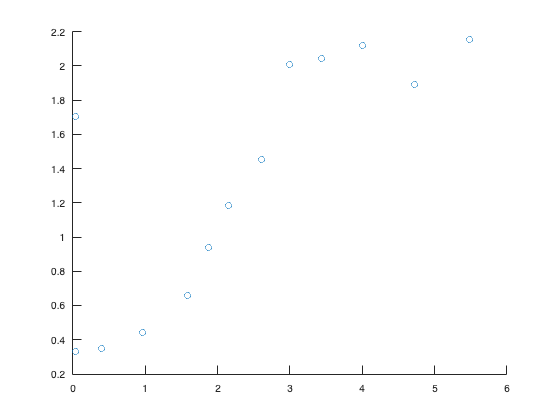

scatter(x, y)

**b) Consider the "logistic" model **$y=\frac{a}{1+be^{-cx}}$** . What does this curve look like on the real line, as **$x\rightarrow -\infty$** and  **$x\rightarrow \infty$**? If our model were "correct" we should see **$\log\left(\frac{a}{y}-1\right)=\alpha+\beta x$** for some value of **$a$** . Explain.**

We have that,


$$y = {a \over 1 + be^{-cx}}$$


Consider the case where $y \ne 0$. It follows that,


$$(1 + be^{-cx}) = {a \over y}$$



$$be^{-cx} = ay^{-1} - 1$$
 

Consider the case where $b > 0$ and $-cx \ne 1$. It follows that,


$$ln(b) - cx = ln(ay^{-1} - 1)$$


Then let,


$$\alpha = ln(b), \beta = -c$$


Then,


$$\alpha + \beta x = ln \big({a \over y} - 1 \big)$$


Note that there are no variables that appear on both sides.

We are interested in the shape of the graph of $y$. So, we rearrange the formula as,


$$y = a(e^{\alpha + \beta x} + 1)^{-1}$$


We observe that $e^{\alpha + \beta x}$ will always be positive. This means that the coefficient on $a$ will lie on the open interval $(0, 1)$. For positive $\beta$ (i.e., negative $c$), as $x \to \infty$, the coefficient will approach 0, and so will $y$. As $x \to -\infty$, the coefficient will approach 1 and $y$ will approach $a$. For negative $\beta$, the reverse will hold.

$y$ will be upper bounded by $a$ if $a$ is positive, and lower bounded by $a$ otherwise. 

We stipulated above that we would consider the case where $y \ne 0$, $b> 0$, and $-cx \ne 1$.

- If $y = 0$ then the behavior of the model will be uninteresting.

- If $b = 0$ or $-cx = 1$, then $y = a$, as is clear on inspection of the model.

- if $b < 0$, we still get a valid model ??

It would make sense then to consider a model with parameters chosen according to these criteria to be "correct".

**c) Try some appropriate values of **$a$** and see graphically if the left hand side appears to be a linear function of x.**

x = linspace(-100, 100, 100)

x =  -100.0000  -97.9798  -95.9596  -93.9394  -91.9192  -89.8990  -87.8788  -85.8586  -83.8384  -81.8182  -79.7980  -77.7778  -75.7576  -73.7374  -71.7172  -69.6970  -67.6768  -65.6566  -63.6364  -61.6162  -59.5960  -57.5758  -55.5556  -53.5354  -51.5152  -49.4949  -47.4747  -45.4545  -43.4343  -41.4141  -39.3939  -37.3737  -35.3535  -33.3333  -31.3131  -29.2929  -27.2727  -25.2525  -23.2323  -21.2121  -19.1919  -17.1717  -15.1515  -13.1313  -11.1111   -9.0909   -7.0707   -5.0505   -3.0303   -1.0101


model = @(x, a, b, c) a./ (1 + b*exp(-c*x));

% a = 1
a = 1

a = 1

y1 = model(x, 1, 1, 1)

y1 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0064    0.0461    0.2670


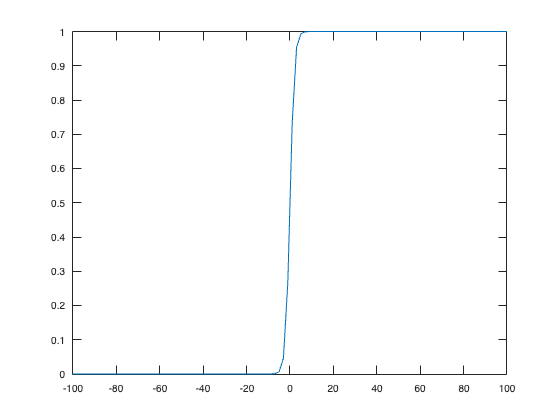

plot(x, y1)

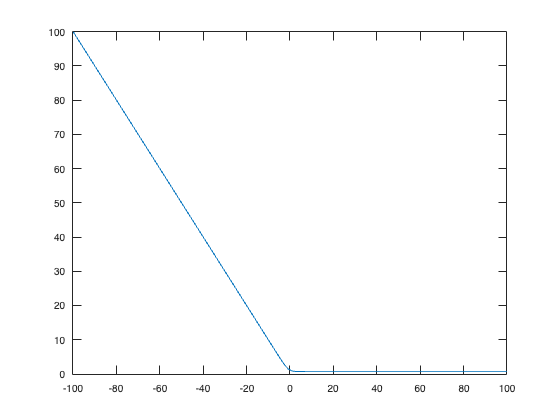

plot(x, log((1./y1) + 1))


% plot(x, 1./(exp(x) + 1))
% plot(x, 10./(exp(x) + 1))
% plot(x, -5./(exp(x) + 1))
% plot(x, model(x, 1, 1, 1))

**d) Choosing some appropriate starting values of the parameters a,b,c, use lsqnonlin.m to find the least squares approximation of the data with the logistic model. Explain your initial choice of a,b,c. Plot this least squares model in the same graph as in part a).  Are you happy? Why not?**

**e) Try the same approach as in part d) with the model **$y=\frac{a}{1+be^{-cx}}+d$**. Are you happy(er) now? Why?**

2. Here is some (x,y) data

P= [     0         0.2         0.4         0.6         0.8           1         1.2         1.4         1.6         1.8           2         2.2         2.4         2.6         2.8           3         3.2         3.4         3.6         3.8           4         4.2         4.4         4.6         4.8           5
0.51454     0.61893       0.709      0.7275     0.77358     0.72706     0.71138     0.69277     0.62293     0.68218      0.6315     0.58225     0.59827     0.51154     0.52011     0.49517     0.48566     0.46616     0.42451      0.4243     0.40579     0.40685      0.4023     0.38962     0.33795      0.3453];
P'

ans =          0    0.5145
    0.2000    0.6189
    0.4000    0.7090
    0.6000    0.7275
    0.8000    0.7736
    1.0000    0.7271
    1.2000    0.7114
    1.4000    0.6928
    1.6000    0.6229
    1.8000    0.6822


a) Plot the data - we are to fit this data with a function of the form $y=\frac{a+bx}{1+cx+dx^2}$

b) First use lsqnonlin to estimate the parameters a,b,c,d that best fit the curve in the least squares sense and plot against the data.  Make some educated initial guesses for a,b,c,d. 

c). if we multiply by the denominator we can rewrite the approximation in the form


$$y\approx a+bx+c(-xy)+d(-yx^2)$$


 Optimal values of a,b,c,d can be found using linear least squares and the normal equations. Do that and compare a,b,c,d with the values obtained in part b). Also plot the approximation 

$y\approx \frac{a+bx}{1+cx+dx^2}$ in the same plot using the values computed in part c).

**3)  Consider the difference equation**


$$x_{n+1}=x_n-.2x_{n-1}-.5x_{n-2}$$


Suppose $x_n = r^n$

$r^{n + 1} = r^n - 0.2r^{n - 1} - 0.5r^{n - 2}$

**a) Use Matlab to calculate the roots of the characteristic polynomial and then write the general solution in terms of real-valued functions**

Use `roots` to find roote

put the roots in e^xipi form

throw it in cos + isin form

both the real and imaginary parts are solutions

**b) Find the specific solution from part a) that satisfies the initial conditions **$x_0=1,x_1=-1,x_2=2$** and then plot the solution for **$n=0,1,..,50$**. (you'll need Matlab to calculate the coefficients in the general solution)**

**c) Run the difference equation directly for the initial conditions in part b), for n=0,1,..,50  and plot it on top of your plot in part b. They should be numerically identical. **